## Assignment 2

Authors:

Kolja Westphal (455887) 

Thineth Gamage (456727)

Tristan de le Cruz Hachiles (405541)

### Task 1:

%% Constants
mu = 398600.4418;            % km^3/s^2, 
Re   = 6378.1363;            % [km]
J2   = 1.08262668e-3;        % [-]

%% Table 1
r1 = [3419.8556; 6019.8260; 2784.6002];   % km
r3 = [2434.9520; 6597.3867; 2521.5231];   % km

t1 = 0.0;                     % s
t3 = 2*60 + 33.04;            % s
dt13 = t3 - t1;               % time of flight

% Class instances
OP = OrbitPropagation;
OD = OrbitDetermination;

%% 1a) Gauss-Lambert: calculate v1 and v2 
[v1, v3] = OD.solve_lamperts_problem_gauss(r1, r3, t1, t3, mu);

%% 1b) Keplarian elements from (r1,v1) and (r3,v3)
[a1, e1, i1, RAAN1, omega1, nu1] = OP.convert_car2kep(r1, v1, mu);
[a3, e3, i3, RAAN3, omega3, nu3] = OP.convert_car2kep(r3, v3, mu);

% Display keplarian elments
% a [km], e [rad], i [rad], RAAN [rad], omega [rad], nu [rad]
a1, e1, i1, RAAN1, omega1, nu1

a1 = 8.2913e+03

e1 = 0.1000

i1 = 0.4363

RAAN1 = 5.2360

omega1 = 2.0595

nu1 = 2.3473e-05

a3, e3, i3, RAAN3, omega3, nu3

a3 = 8.2913e+03

e3 = 0.1000

i3 = 0.4363

RAAN3 = 5.2360

omega3 = 2.0595

nu3 = 0.1571

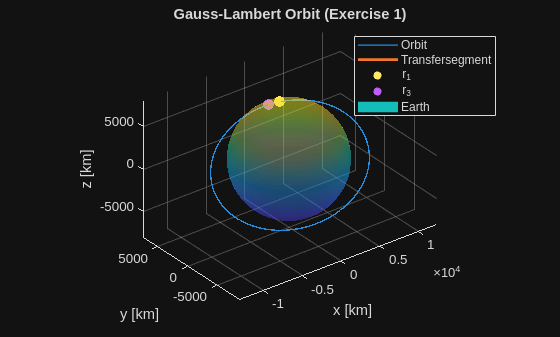

%% 1c) propagate Orbit (Runge-Kutta) 
T = 2*pi * sqrt(a1^3 / mu);   % Orbital period [s]

dtStep = T / 500;             % time step [s]
[tOrb, rOrb, vOrb] = OP.propagate_orbit_EoM_rk4(r1, v1, 0, T, dtStep, mu, Re, J2);

% transfersegment between r1 and r2
[tSeg, rSeg, vSeg] = OP.propagate_orbit_EoM_rk4(r1, v1, t1, t3, dtStep, mu, Re, J2);

%% Plot: Orbit, transfer segment and vectors
figure; hold on; grid on; axis equal;

% Full orbit
plot3(rOrb(:,1), rOrb(:,2), rOrb(:,3), 'LineWidth', 1);

% Transfersegment
plot3(rSeg(:,1), rSeg(:,2), rSeg(:,3), 'LineWidth', 2);

% Vector points r1 and r3
scatter3(r1(1), r1(2), r1(3), 60, 'filled');
scatter3(r3(1), r3(2), r3(3), 60, 'filled');

% Earth
[xe, ye, ze] = sphere(40);
surf(Re*xe, Re*ye, Re*ze, 'FaceAlpha', 0.3, 'EdgeColor', 'none');

xlabel('x [km]');
ylabel('y [km]');
zlabel('z [km]');
legend('Orbit', 'Transfersegment', 'r_1', 'r_3', 'Earth');
title('Gauss-Lambert Orbit (Exercise 1)');
view(3);

### Task 2:

% Table data
r1 = [0; 0; 6378.137];   % km
r2 = [0; -4464.696; -5102.509];   % km
r3 = [0; 5740.323; 3189.068];   % km

%% 2a) Gibbs-Method: solve for v_2 [km/s]
[v1, v2, v3] = OD.solve_gibbs_method(r1, r2, r3, mu);
v2

v2 =          0
    5.5311
   -5.1918


% Compare with given and calculate norm
v2_test = [0; 5.531148; -5.191806];  % km/s
diff  = norm(v2 - v2_test)

diff = 2.5782e-07


%% 2b) Keplar elements from r2 and v2
[a2, e2, i2, RAAN2, omega2, nu2] = OP.convert_car2kep(r2, v2, mu);

% a [km], e [rad], i [rad], RAAN [rad], omega [rad], nu [rad]
a2, e2, i2, RAAN2, omega2, nu2

a2 = 6.6398e+03

e2 = 0.0408

i2 = 1.5708

RAAN2 = 1.5708

omega2 = 1.8442

nu2 = 2.1494

### Task 4:

% Table data
r1 = [3419.8556; 6019.8260; 2784.6002];   % km
r2 = [2935.9119; 6326.1832; 2660.5958];   % km
r3 = [2434.9520; 6597.3867; 2521.5231];   % km

t1 = 0.0;                            % 0.0 s
t2 = 1*60 + 16.48;                   % 1 min 16.48 s = 76.48 s
t3 = 2*60 + 33.04;                   % 2 min 33.04 s = 153.04 s

%% 3a) Herrick-Gibbs: calculate v2 [km/s]
v2_HG = OD.solve_gibbs_herrik_method(r1, r2, r3, [t1; t2; t3], mu)

v2_HG =    -6.4416
    3.7776
   -1.7206


% Compare with given and calculate norm
v2_test = [-6.4416; 3.7776; -1.7205];   % km/s 
diff = norm(v2_HG - v2_test)

diff = 8.9657e-05

%% 3b) Kepler elements from r2 and v2_HG
[a2, e2, i2, RAAN2, omega2, nu2] = OP.convert_car2kep(r2, v2_HG, mu);

% a [km], e [rad], i [rad], RAAN [rad], omega [rad], nu [rad]
a2, e2, i2, RAAN2, omega2, nu2

a3 = 8.2913e+03

e3 = 0.1000

i3 = 0.4363

RAAN3 = 5.2360

omega3 = 2.0595

nu3 = 0.0785

### Task 3:

% extract lat/long
lla = Sat11Access(62, ["lat","long"]).Variables;

% build UTC datetime from table columns
trow = Sat11Access(62, ["year","month","day","h","min","sec"]).Variables;

% create R_GS from lla
R_GS = repmat(lla2eci([lla, Re], trow)', 1, 3); 

% Extract numeric values for each row
vals62 = Sat11Access{62, ["delta", "alpha"]};
vals70 = Sat11Access{70, ["delta", "alpha"]};
vals74 = Sat11Access{74, ["delta", "alpha"]};

trows = Sat11Access([62, 70, 74], ["year","month","day","h","min","sec"]).Variables;

L_i = @(delta, alpha) [cos(delta) * cos(alpha); cos(delta) * sin(alpha); sin(delta)]


% Call the function
L_62 = L_i(vals62(1), vals62(2));
L_70 = L_i(vals70(1), vals70(2));
L_74 = L_i(vals74(1), vals74(2));

LOS = [L_62, L_70, L_74];

[R, vv_2] = OD.solve_angles_only_approach_extended(LOS, R_GS, posixtime(datetime(trows)), mu, 1E-9, 100)

R = 1.0e+07 *

    1.0389    0.1839    0.2436
    1.1418   -0.1060    0.7298
    0.2103   -0.4742    0.8165


vv_2 =    -0.2559
   -0.1743
    0.1258


%% 4b) Kepler elements from r2 and v2_HG
[a2, e2, i2, RAAN2, omega2, nu2] = OP.convert_car2kep(R(:,2), vv_2, mu);

% a [km], e [rad], i [rad], RAAN [rad], omega [rad], nu [rad]
a2, e2, i2, RAAN2, omega2, nu2